# XPlane NN Error Plots Autolander 

This program aims to provide insight in characterizing the output behahavior of a NN by plotting the output and error in output against state information from an autolander scenario. 

clear variables; close all; clc;

## CSV Reader

%Data 1 and Data 2 are just comparing two different trials
%Make sure data is moved over to the MATLAB folder 
csvData1 = readtable('./2024-4-2/2024-4-2/Trial15-12464_states.csv')

csvData1 = 2608×11 table
      phi        theta       psi         x          y         y_pred       h         h_err       h_err_pred    y_err_NN    h_err_NN
    ________    _______    ________    _____    _________    ________    ______    __________    __________    ________    ________

           0          0    7.63e-07    12464            0     -7.1582    1029.4      0.020996     -13.347       7.1582      13.368 
     0.06027    -2.3108      0.1043    12458    -0.074176     -7.8804    1029.4      -0.28504     -17.624       7.8062      17.339 
     0.08834    -5.3722     0.36934    12452     -0.13869     -13.032   

csvData2 = readtable('./autoland_errors/2024-3-25/Trial11-12000_states.csv')

csvData2 = 2555×11 table
       phi        theta        psi          x           y          y_pred       h        h_err      h_err_pred    y_err_NN    h_err_NN
    _________    _______    __________    _____    ___________    ________    ______    ________    __________    ________    ________

            0          0    7.6294e-07    12000    -0.00072853     -7.9823    1005.1    0.020085     -50.694        7.9816     50.714 
    0.0065927    -1.9302        0.1574    11993      -0.078373     -1.3868    1005.1    -0.29599     -46.135        1.3084     45.839 
     0.038307    -5.9201       0.40276    11987       -0.147


error_h1 = csvData1.h_err_NN;  %NN Error, height offset                   
error_y1 = csvData1.y_err_NN; %NN Error, crosstrack offset
error_h_pred1 = csvData1.h_err_pred;  %NN Output- Predicted height offset
error_y_pred1 = csvData1.y_pred;  %NN Output- Predicted crosstrack offset 
error_h_actual1 = csvData1.h_err; %True height error based on state info 

%True State Information 
phi1 = csvData1.phi; %Roll 
theta1 = csvData1.theta; %Pitch 
psi1 = csvData1.psi; %Yaw
x1 = csvData1.x; %Horizontal distance from runway 
y1 = csvData1.y; %True crosstrack offset 
h1 = csvData1.h; %True Height offset 

%Same as above 
error_h2 = csvData2.h_err_NN; 
error_y2 = csvData2.y_err_NN; 
error_h_pred2 = csvData2.h_err_pred; 
error_y_pred2 = csvData2.y_pred; 
error_h_actual2 = csvData2.h_err; 

phi2 = csvData2.phi; 
theta2 = csvData2.theta; 
psi2 = csvData2.psi; 
x2 = csvData2.x; 
y2 = csvData2.y; 
h2 = csvData2.h; 

## Height Error Plots 

All distance units are in meters, all angular units are in degrees. 

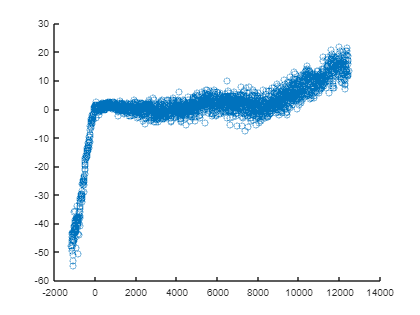


scatter(x1, error_h1);

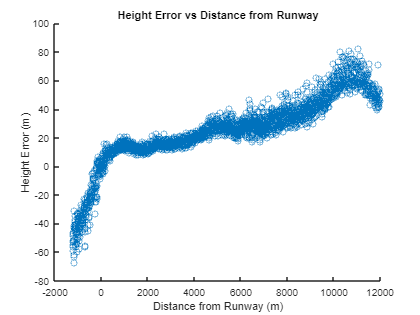

hold on; 
scatter(x2, error_h2);
legend on; 
axis auto; 
title('Height Error NN vs Distance from Runway');
xlabel('Distance from Runway (m)');
ylabel('Height Error NN (m)');

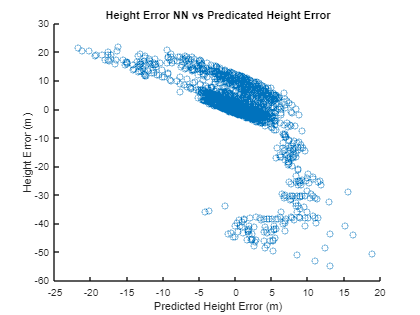


% hold off; 
% scatter(h1, error_h1);
% axis auto;
% title('Height Error NN vs True Absolute Height');
% xlabel('True Absolute Height (m)');
% ylabel('Height Error NN (m)');

scatter(error_h_pred1, error_h1);
axis auto; 
title('Height Error NN vs Predicted Height Offset');
xlabel('Predicted Height Offset (m)');
ylabel('Height Error NN(m)');

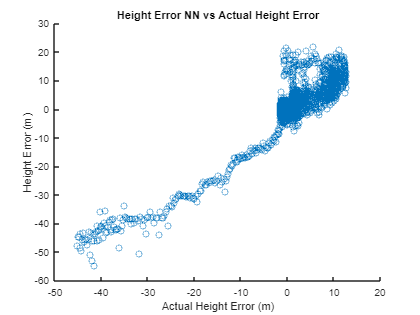


scatter(error_h_actual1, error_h1);
axis auto; 
title('Height Error NN vs Actual Height Offset');
xlabel('Actual Height Offset (m)');
ylabel('Height Error (m)');

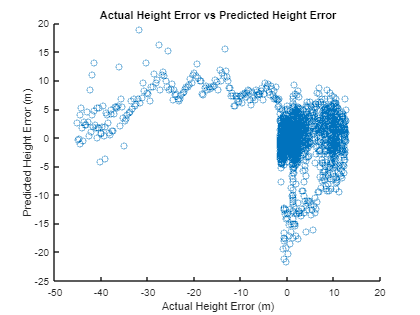


scatter(error_h_actual1, error_h_pred1);
axis auto; 
title('Actual Height Offset vs Predicted Height Offset');
xlabel('Actual Height Offset (m)');
ylabel('Predicted Height Offset (m)');

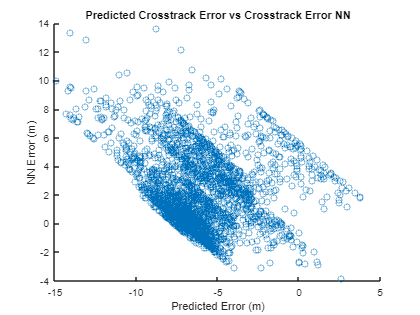


scatter(error_y_pred1, error_y1);
axis auto; 
title('Predicted Crosstrack Offset vs Crosstrack Error NN');
xlabel('Predicted Crosstrack Offset (m)');
ylabel('Crosstrack Error NN (m)');

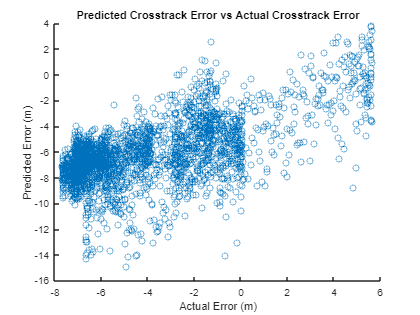


scatter(y1, error_y_pred1);
axis auto; 
title('Predicted Crosstrack Offset vs Actual Crosstrack Offset');
xlabel('Actual Crosstack Offset (m)');
ylabel('Predicted Crosstrack Offset(m)');

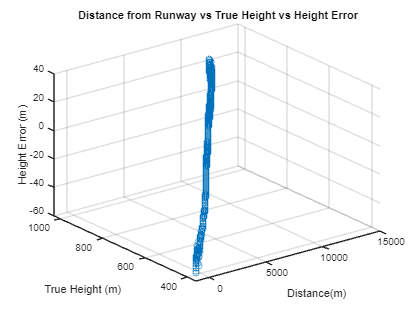


scatter3(x1, h1, error_h1);
%axis equal;
title('Distance from Runway vs True Absolute Height vs Height Error NN');
xlabel('Distance(m)');
ylabel('True Absolute Height (m)');
zlabel('Height Error NN (m)');

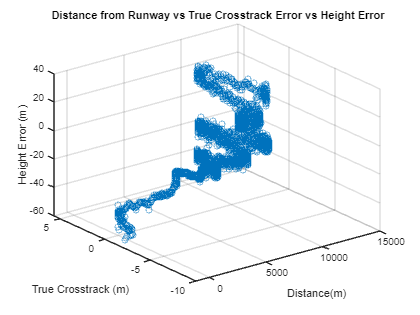


scatter3(x1, y1, error_h1);
%axis equal;
title('Distance from Runway vs True Crosstrack Offset vs Height Error NN');
xlabel('Distance(m)');
ylabel('True Crosstrack Offset (m)');
zlabel('Height Error NN(m)');

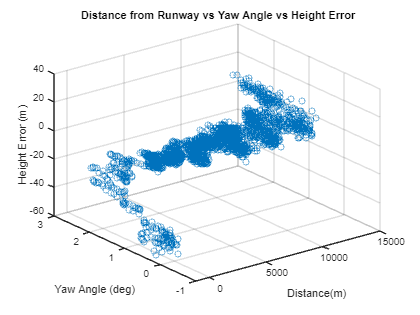


scatter3(x1, psi1, error_h1);
%axis equal;
title('Distance from Runway vs Yaw Angle vs Height Error NN');
xlabel('Distance(m)');
ylabel('Yaw Angle (deg)');
zlabel('Height Error NN (m)');

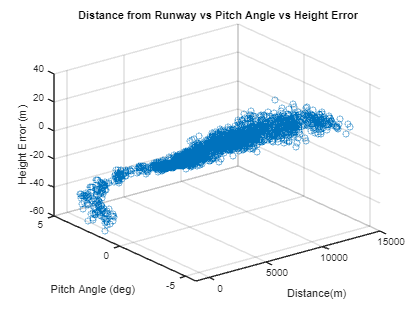


scatter3(x1, theta1, error_h1);
%axis equal;
title('Distance from Runway vs Pitch Angle vs Height Error NN ');
xlabel('Distance(m)');
ylabel('Pitch Angle (deg)');
zlabel('Height Error NN (m)');

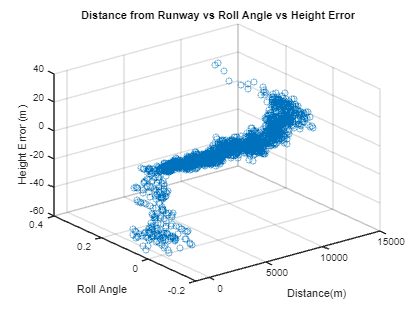


scatter3(x1, phi1, error_h1);
%axis equal;
title('Distance from Runway vs Roll Angle vs Height Error NN');
xlabel('Distance(m)');
ylabel('Roll Angle');
zlabel('Height Error NN (m)');

## Crosstrack Error Plots 

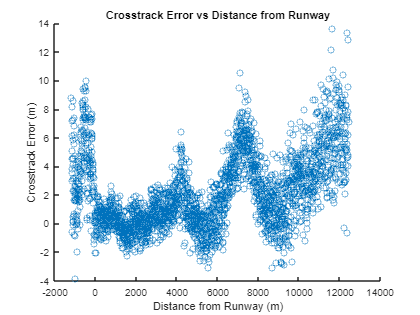

scatter(x1, error_y1);
axis auto; 
title('Crosstrack Error NN vs Distance from Runway');
xlabel('Distance from Runway (m)');
ylabel('Crosstrack Error NN (m)');

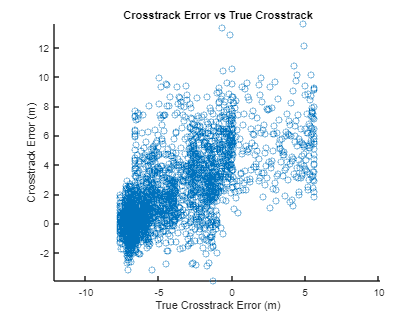


scatter(y1, error_y1);
axis equal;
title('Crosstrack Error NN vs True Crosstrack Offset');
xlabel('True Crosstrack Offset (m)');
ylabel('Crosstrack Error NN (m)');

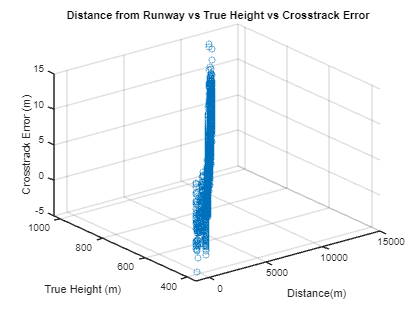


scatter3(x1, h1, error_y1);
%axis equal;
title('Distance from Runway vs True Absolute Height vs Crosstrack Error NN');
xlabel('Distance(m)');
ylabel('True Absolute Height (m)');
zlabel('Crosstrack Error NN (m)');

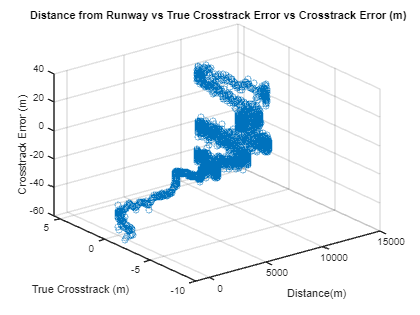


scatter3(x1, y1, error_h1);
%axis equal;
title('Distance from Runway vs True Crosstrack Offset vs Crosstrack Error NN (m)');
xlabel('Distance(m)');
ylabel('True Crosstrack Offset(m)');
zlabel('Crosstrack Error NN (m)');

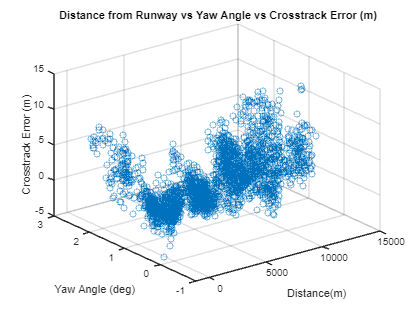


scatter3(x1, psi1, error_y1);
%axis equal;
title('Distance from Runway vs Yaw Angle vs Crosstrack Error NN(m)');
xlabel('Distance(m)');
ylabel('Yaw Angle (deg)');
zlabel('Crosstrack Error NN (m)');

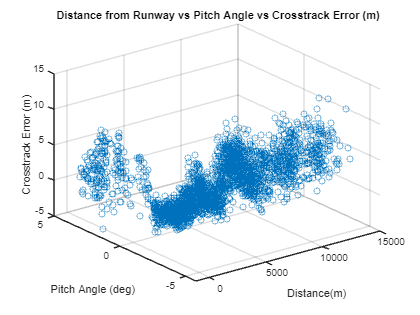


scatter3(x1, theta1, error_y1);
%axis equal;
title('Distance from Runway vs Pitch Angle vs Crosstrack Error NN(m)');
xlabel('Distance(m)');
ylabel('Pitch Angle (deg)');
zlabel('Crosstrack Error NN(m)');

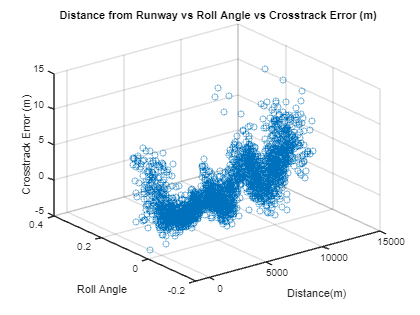



scatter3(x1, phi1, error_y1);
%axis equal;
title('Distance from Runway vs Roll Angle vs Crosstrack Error NN (m)');
xlabel('Distance(m)');
ylabel('Roll Angle');
zlabel('Crosstrack Error NN (m)');